Implementing the 2D barebones FDTD acoustic code

c = 1500;        %speed of sound in water (m/s)
SIZE = 100;       %size of each array
dt = 0.0001;     %temporal step size
dx = 1;          %spatial step size
rho = 997;       %density of water in kg/m^3
Sc = (c*dt)/dx;  %courant number
Pr = zeros(SIZE,SIZE);%pressure matrix
vx = zeros(SIZE,SIZE);%x-velocity matrix
vy = zeros(SIZE,SIZE);%y-velocity matrix
maxTime = 0.02;       %max time for the simulation to run
maxN = maxTime/dt;    %total number of frames
backscatter = zeros(maxN,1); % Array to store backscatter data

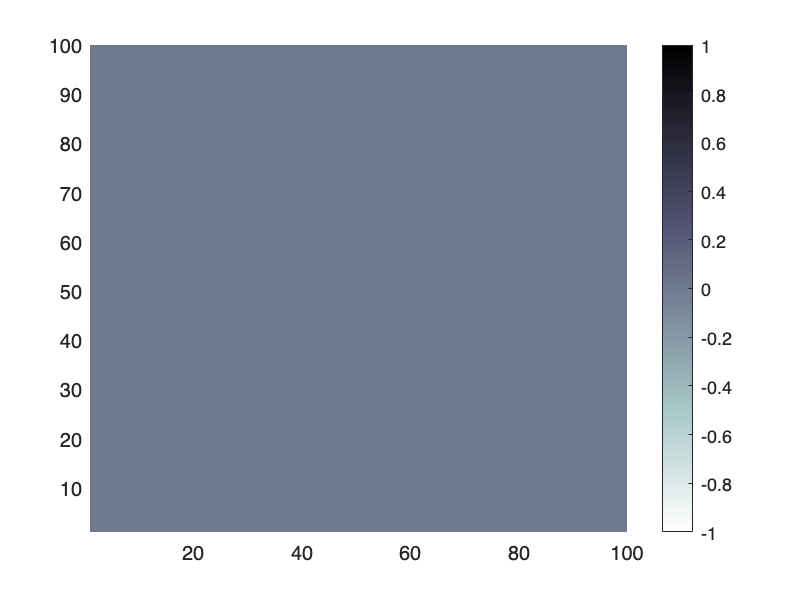

pl = abs(Pr(:,:)); %absolute value of pressure
h2 = pcolor(pl); 
colormap(flipud(bone));
colorbar;
xlim([1 SIZE]);
ylim([1 SIZE]);
shading interp;

%Source
fc = 0.075;     % Cutoff frequency (normalised 0.5=nyquist)
n0 = 30;        % Initial delay (samples)
sigma=sqrt(2*log(2))/(2*pi*(fc/dt)); %flow resistivity
n=0:maxN;
srcFn=exp(-dt^2*(n-n0).^2/(2*sigma^2));
srcFn=filter([1 -1], [1 -0.995], srcFn); % DC Blocker

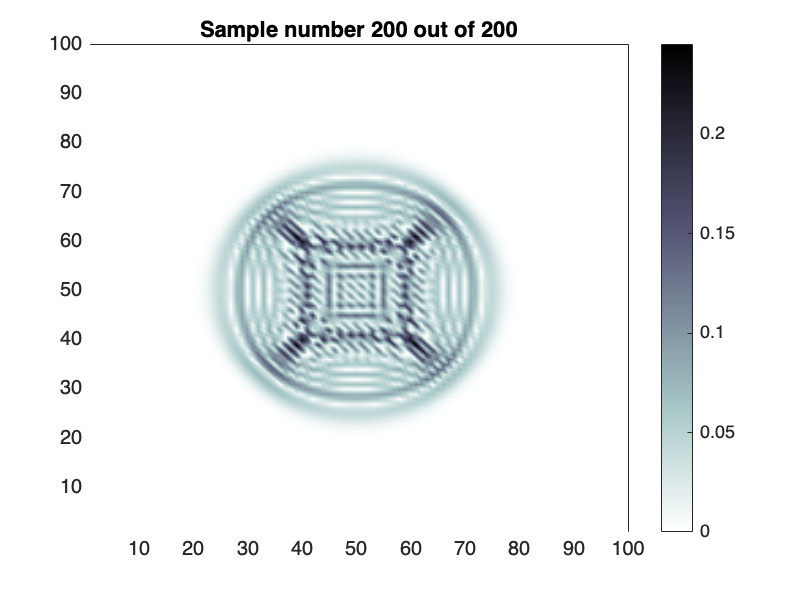


for count=1:maxN
    time = count*dt; %convert counter to time value
    for mm=1:SIZE-1
        %temp variable to store value in previous time step
        vx_old = vx(mm,:);
        %update x-velocity
        vx(mm,:) = vx_old - (Sc/(c*rho))*(Pr(mm+1,:)-Pr(mm,:));
    end
    for nn=1:SIZE-1
        %temp variable to store value in previous time step
        vy_old = vy(:,nn);
        %update y-velocity
        vy(:,nn) = vy_old - (Sc/(c*rho))*(Pr(:,nn+1)-Pr(:,nn));
    end
    for mm=2:SIZE
        for nn=2:SIZE
            %temp variable to store value in previous time step
            Pr_old = Pr(mm,nn);
            %update pressure
            Pr(mm,nn) = Pr_old - (c*rho*Sc)*(vx(mm,nn)-vx(mm-1,nn)...
                +vy(mm,nn)-vy(mm,nn-1));
        end
    end
    %hardwire a source node
    %vx(SIZE/2,SIZE/2) = 1/(100*(time+1));
    Pr(SIZE/2,SIZE/2) = Pr(SIZE/2,SIZE/2) + srcFn(count);
    backscatter(mm) = Pr(50,40);
    pl = abs(Pr(:,:));
    set(h2,'CData',pl);
    title(sprintf('Sample number %d out of %d',count,maxN));
    drawnow;
end

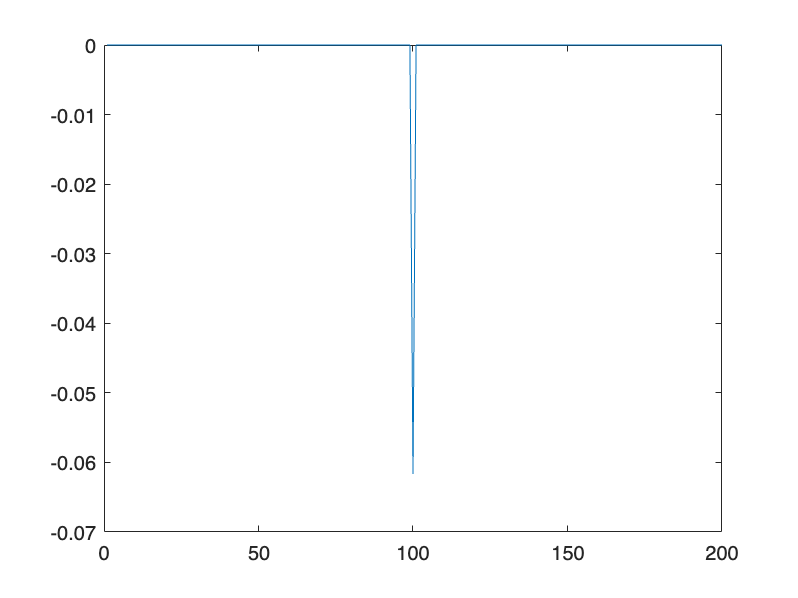

plot(backscatter)